Question 03

cable;
x = A\b;
A1 = x(1)

A1 = 7.1888e-04

B1 = x(2)

B1 = -1.3749e-06

A21 = x(3)

A21 = 7.2748e-04

B21 = x(4)

B21 = -1.8032e-06

A22 = x(5)

A22 = 7.2748e-04

B22 = x(6)

B22 = -1.8032e-06

Question 04

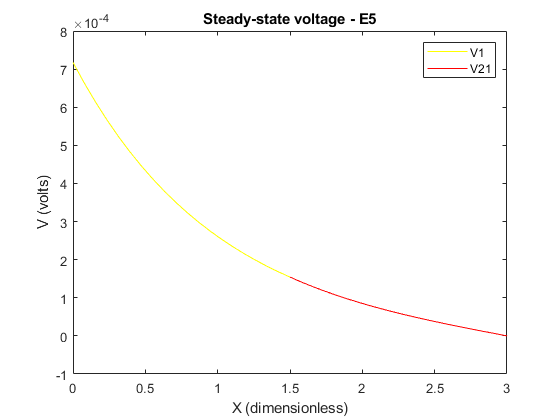

figure;
y1 = linspace (0,l1,20);
y21 = linspace (l1,l21,20);
y22 = linspace (l1,l22,20);
v1 = A1*exp(-y1) + B1*exp(y1);
v21 = A21*exp(-y21) + B21*exp(y21);
v22 = A22*exp(-y22) + B22*exp(y22);
plot (y1,v1, 'y-',y21, v21, 'r-')
xlabel('X (dimensionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend({'V1','V21'})

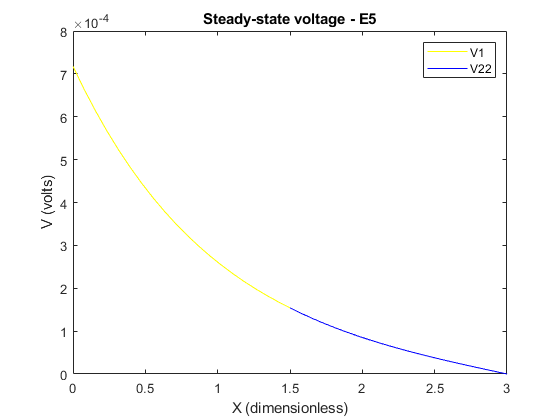


figure;
plot (y1,v1, 'y-',y22, v22, 'b-')
xlabel('X (dimensionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend({'V1','V22'})

Question 05

part (a)

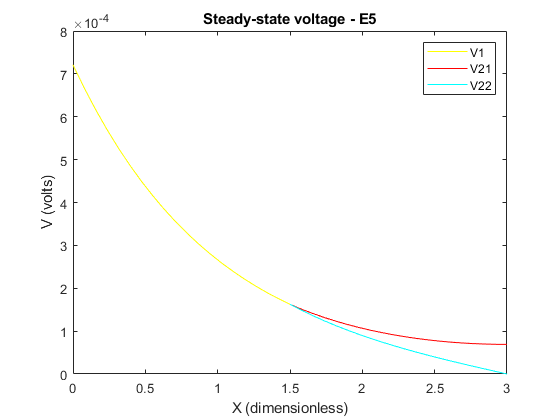

original_A = A;

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
x=A\b;
y1 = linspace (0,l1,20);
y21 = linspace (l1,l21,20);
y22 = linspace (l1,l22,20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);
plot (y1,v1, 'y-',y21, v21, 'r-',y22, v22, 'cyan-')
xlabel('X (dimensionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend({'V1','V21','V22'})

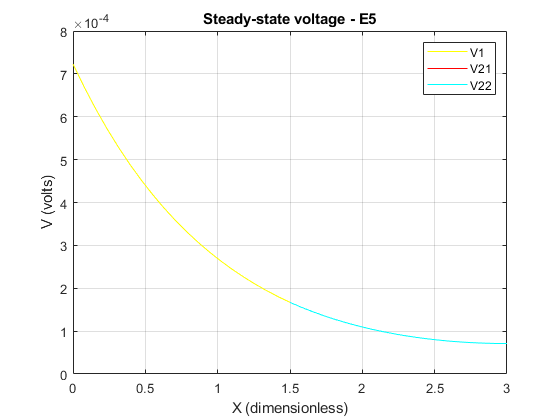

A(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x=A\b;
y1 = linspace (0,l1,20);
y21 = linspace (l1,l21,20);
y22 = linspace (l1,l22,20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);
plot (y1,v1, 'y-',y21, v21, 'r-',y22, v22, 'cyan-')
xlabel('X (dimensionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
grid on
legend({'V1','V21','V22'})

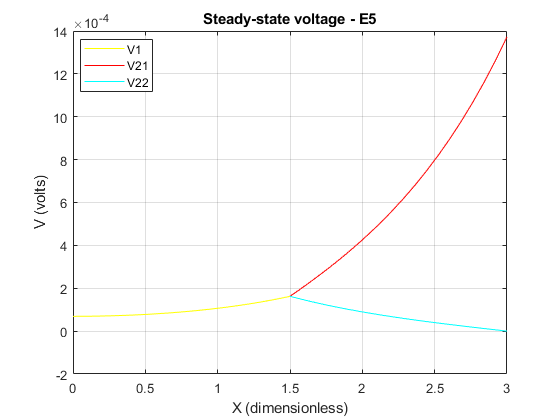

b(1) = 0;
b(2) = rl21*iapp;
A(3,:) = [0 0 0 0 exp(-l22) exp(l22)];
x=A\b;
y1 = linspace (0,l1,20);
y21 = linspace (l1,l21,20);
y22 = linspace (l1,l22,20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);
plot (y1,v1, 'y-',y21, v21, 'r-',y22, v22, 'cyan-')
xlabel('X (dimensionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
grid on
legend({'V1','V21','V22'},'Location',"best")